clear;
clc;
close all;

% Define the number of samples and the true parameter values
N = 100;
lambda_true = 6;
theta_true = 5;

% Number of Monte Carlo runs
MC = 10;
tol=1e-6;

%Noise.
variance = 0.7;
wn = randn(N,1)*variance;

% Weibull Distribution.
X = wblrnd(theta_true, lambda_true, N, 1) + wn;

% Compute the score function and its derivative w.r.t. lambda and k
dlnL_dlambda = @(lambda, k, x) (k/lambda) - ((x/lambda).^k).*log(x/lambda);
dlnL_dk = @(lambda, k, x) log(x/lambda) - ((x/lambda).^k).*log(x/lambda);

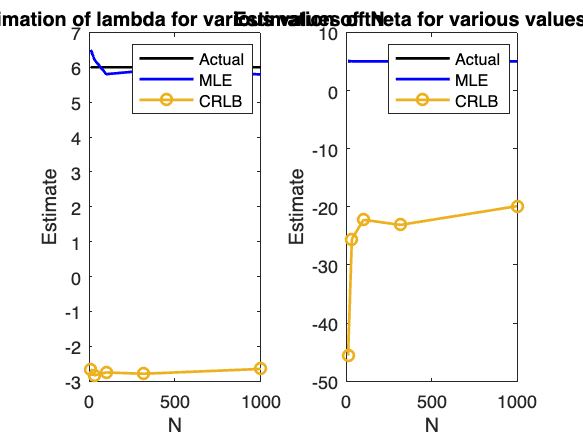

%Varying the length of Signal N.
N_MC=round(logspace(1,3,5));

lambda_MLE_est=[];
theta_MLE_est=[];
lambda_crlb=[];
theta_crlb=[];

for iter=1:size(N_MC,2)
    lambda_MLE=[];
    theta_MLE=[];
    CRLB_lambda=[];
    CRLB_k=[];

    for runs=1:MC
        N=N_MC(iter);
        n=0:N-1;
        variance = 0.2;
        wn = randn(N,1)*variance;
        % Generate a new random sample for each Monte Carlo run
        X = wblrnd(theta_true, lambda_true, N, 1) +wn;

        % Compute the elements of the Fisher information matrix
        I_lambda_lambda = -mean(dlnL_dlambda(lambda_true, theta_true, X).^2);
        I_k_k = -mean(dlnL_dk(lambda_true, theta_true, X).^2);
        I_lambda_k = -mean(dlnL_dlambda(lambda_true, theta_true, X).*dlnL_dk(lambda_true, theta_true, X));

        % Compute the inverse of the Fisher information matrix
        FIM = [I_lambda_lambda I_lambda_k; I_lambda_k I_k_k];
        invFIM = inv(FIM);

        % Compute the Cramer-Rao lower bound for lambda and theta
        CRLB_lambda = [CRLB_lambda invFIM(1,1)];
        CRLB_k = [CRLB_k invFIM(2,2)];

        %Maximum Likelihood Estimation.

        %Newton-Raphson Method for lambda.
        lambda_est= newton_raphson_lambda(theta_true,N,X,4,tol);
        lambda_MLE=[lambda_MLE lambda_est];

        %Closed form solution for theta.
        theta_est = ((1/N)*sum(X.^lambda_est))^(1/lambda_est);
        theta_MLE=[theta_MLE theta_est];
    end
    lambda_crlb=[lambda_crlb mean(CRLB_lambda)];
    theta_crlb=[theta_crlb mean(CRLB_k)];


    lambda_MLE_est=[lambda_MLE_est mean(lambda_MLE)];
    theta_MLE_est=[theta_MLE_est mean(theta_MLE)];
end

%Plotting the estimated lambda and theta for various values of N.
figure;
subplot(1,2,1);
plot(N_MC,ones(1,size(N_MC,2))*lambda_true,'k','LineWidth',1.5);
hold on;
plot(N_MC,lambda_MLE_est,'b','LineWidth',1.5);
hold on;
plot(N_MC,lambda_crlb,'o-','LineWidth',1.5);
hold off;
legend('Actual','MLE','CRLB');
title('Estimation of lambda for various values of N');
xlabel('N');
ylabel('Estimate');
%ylim([-0.3 0.3]);
subplot(1,2,2);
plot(N_MC,ones(1,size(N_MC,2))*theta_true,'k','LineWidth',1.5);
hold on;
plot(N_MC,theta_MLE_est,'b','LineWidth',1.5);
hold on;
plot(N_MC,theta_crlb,'o-','LineWidth',1.5);
hold off;
legend('Actual','MLE','CRLB');
title('Estimation of theta for various values of N');
xlabel('N');
ylabel('Estimate');

%ylim([4 6]);

%Varying the theta and finding lambda.
theta_MC=1:5;
N=1000;

lambda_MLE_est=[];
theta_MLE_est=[];
lambda_crlb=[];
theta_crlb=[];

for iter=1:size(theta_MC,2)
    lambda_MLE=[];
    theta_MLE=[];
    CRLB_lambda=[];
    CRLB_k=[];

    for runs=1:MC
        n=0:N-1;
        theta = theta_MC(iter);
        wn = randn(N,1)*variance;
        % Generate a new random sample for each Monte Carlo run
        X = wblrnd(theta, lambda_true, N, 1) + wn;

        % Compute the elements of the Fisher information matrix
        I_lambda_lambda = -mean(dlnL_dlambda(lambda_true, theta, X).^2);
        I_k_k = -mean(dlnL_dk(lambda_true, theta, X).^2);
        I_lambda_k = -mean(dlnL_dlambda(lambda_true, theta, X).*dlnL_dk(lambda_true, theta, X));

        % Compute the inverse of the Fisher information matrix
        FIM = [I_lambda_lambda I_lambda_k; I_lambda_k I_k_k];
        invFIM = inv(FIM);

        % Compute the Cramer-Rao lower bound for lambda and theta
        CRLB_lambda = [CRLB_lambda invFIM(1,1)];
        CRLB_k = [CRLB_k invFIM(2,2)];

        %Maximum Likelihood Estimation.

        %Newton-Raphson Method for lambda.
        lambda_est= newton_raphson_lambda(theta,N,X,3,tol);
        lambda_MLE=[lambda_MLE lambda_est];

        %Closed form solution for theta.
        theta_est = ((1/N)*sum(X.^lambda_est))^(1/lambda_est);
        theta_MLE=[theta_MLE theta_est];
    end
    lambda_crlb=[lambda_crlb mean(CRLB_lambda)];
    theta_crlb=[theta_crlb mean(CRLB_k)];


    lambda_MLE_est=[lambda_MLE_est mean(lambda_MLE)];
    theta_MLE_est=[theta_MLE_est mean(theta_MLE)];
end

%Plotting the estimated lambda and theta for various values of initial lambda.
figure;
subplot(1,2,1);
plot(theta_MC,ones(1,size(theta_MC,2))*lambda_true,'k','LineWidth',1.5);
hold on;
plot(theta_MC,lambda_MLE_est,'b','LineWidth',1.5);

hold on;
plot(theta_MC,lambda_crlb,'o-','LineWidth',1.5);

hold off;
legend('Actual','MLE','CRLB');
title('Estimation of lambda for various values of theta');
xlabel('theta');
ylabel('Estimate');
%ylim([-0.3 0.3]);
subplot(1,2,2);
plot(theta_MC,theta_MC,'k','LineWidth',1.5);
hold on;
plot(theta_MC,theta_MLE_est,'b','LineWidth',1.5);

hold on;
plot(theta_MC,theta_crlb,'o-','LineWidth',1.5);

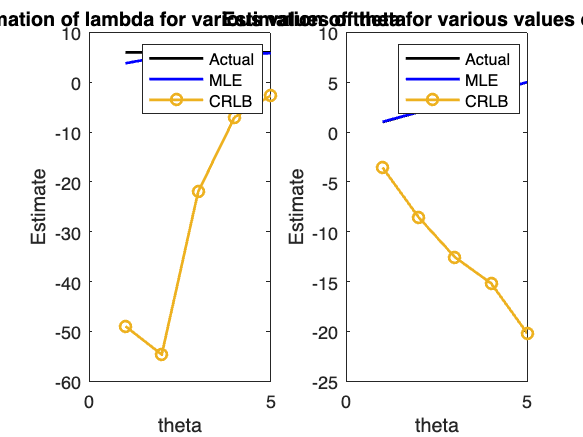

hold off;
legend('Actual','MLE','CRLB');
title('Estimation of theta for various values of theta');
xlabel('theta');
ylabel('Estimate');

%Varying the lambda and finding theta.
lambda_MC=1:2:10;

lambda_MLE_est=[];
theta_MLE_est=[];
lambda_crlb=[];
theta_crlb=[];

for iter=1:size(lambda_MC,2)
    lambda_MLE=[];
    theta_MLE=[];
    CRLB_lambda=[];
    CRLB_k=[];

    for runs=1:MC
        lambda=lambda_MC(iter);
        n=0:N-1;
        variance = 0.6;
        wn = randn(N,1)*variance;
        % Generate a new random sample for each Monte Carlo run
        X = wblrnd(theta_true, lambda, N, 1) +wn;

        % Compute the elements of the Fisher information matrix
        I_lambda_lambda = -mean(dlnL_dlambda(lambda, theta_true, X).^2);
        I_k_k = -mean(dlnL_dk(lambda, theta_true, X).^2);
        I_lambda_k = -mean(dlnL_dlambda(lambda, theta_true, X).*dlnL_dk(lambda, theta_true, X));

        % Compute the inverse of the Fisher information matrix
        FIM = [I_lambda_lambda I_lambda_k; I_lambda_k I_k_k];
        invFIM = inv(FIM);

        % Compute the Cramer-Rao lower bound for lambda and theta
        CRLB_lambda = [CRLB_lambda invFIM(1,1)];
        CRLB_k = [CRLB_k invFIM(2,2)];

        %Maximum Likelihood Estimation.

        %Newton-Raphson Method for lambda.
        lambda_est= newton_raphson_lambda(theta_true,N,X,4,tol);
        lambda_MLE=[lambda_MLE lambda_est];

        %Closed form solution for theta.
        theta_est = ((1/N)*sum(X.^lambda_est))^(1/lambda_est);
        theta_MLE=[theta_MLE theta_est];
    end
    lambda_crlb=[lambda_crlb mean(CRLB_lambda)];
    theta_crlb=[theta_crlb mean(CRLB_k)];


    lambda_MLE_est=[lambda_MLE_est mean(lambda_MLE)];
    theta_MLE_est=[theta_MLE_est mean(theta_MLE)];
end

%Plotting the estimated lambda and theta for various values of N.
figure;
subplot(1,2,1);
plot(lambda_MC,lambda_MC,'k','LineWidth',1.5);
hold on;
plot(lambda_MC,lambda_MLE_est,'b','LineWidth',1.5);

hold on;
plot(lambda_MC,lambda_crlb,'o-','LineWidth',1.5);

hold off;
legend('Actual','MLE','CRLB');
title('Estimation of lambda for various values of lambda');
xlabel('lambda');
ylabel('Estimate');
%ylim([-0.3 0.3]);
subplot(1,2,2);
plot(lambda_MC,ones(1,size(N_MC,2))*theta_true,'k','LineWidth',1.5);
hold on;
plot(lambda_MC,theta_MLE_est,'b','LineWidth',1.5);

hold on;
plot(lambda_MC,theta_crlb,'o-','LineWidth',1.5);

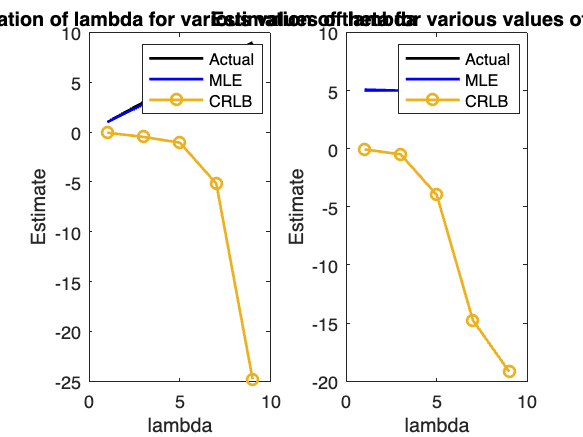

hold off;
legend('Actual','MLE','CRLB');
title('Estimation of theta for various values of lambda');
xlabel('lambda');
ylabel('Estimate');

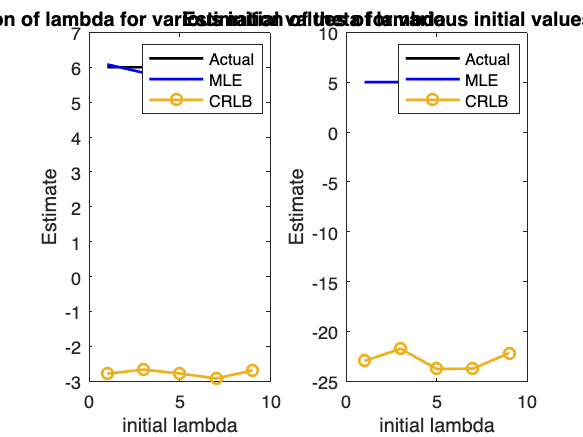

%Varying the initial guess of lambda.
lambda_MC=1:2:10;
N=100;

lambda_MLE_est=[];
theta_MLE_est=[];
lambda_crlb=[];
theta_crlb=[];

for iter=1:size(lambda_MC,2)
    lambda_MLE=[];
    theta_MLE=[];
    CRLB_lambda=[];
    CRLB_k=[];

    for runs=1:MC
        n=0:N-1;
        variance = 0.2;
        wn = randn(N,1)*variance;
        % Generate a new random sample for each Monte Carlo run
        X = wblrnd(theta_true, lambda_true, N, 1) + wn;

        % Compute the elements of the Fisher information matrix
        I_lambda_lambda = -mean(dlnL_dlambda(lambda_true, theta_true, X).^2);
        I_k_k = -mean(dlnL_dk(lambda_true, theta_true, X).^2);
        I_lambda_k = -mean(dlnL_dlambda(lambda_true, theta_true, X).*dlnL_dk(lambda_true, theta_true, X));

        % Compute the inverse of the Fisher information matrix
        FIM = [I_lambda_lambda I_lambda_k; I_lambda_k I_k_k];
        invFIM = inv(FIM);

        % Compute the Cramer-Rao lower bound for lambda and theta
        CRLB_lambda = [CRLB_lambda invFIM(1,1)];
        CRLB_k = [CRLB_k invFIM(2,2)];

        %Maximum Likelihood Estimation.

        %Newton-Raphson Method for lambda.
        lambda_est= newton_raphson_lambda(theta_true,N,X,lambda_MC(iter),tol);
        lambda_MLE=[lambda_MLE lambda_est];

        %Closed form solution for theta.
        theta_est = ((1/N)*sum(X.^lambda_est))^(1/lambda_est);
        theta_MLE=[theta_MLE theta_est];
    end
    lambda_crlb=[lambda_crlb mean(CRLB_lambda)];
    theta_crlb=[theta_crlb mean(CRLB_k)];


    lambda_MLE_est=[lambda_MLE_est mean(lambda_MLE)];
    theta_MLE_est=[theta_MLE_est mean(theta_MLE)];
end

%Plotting the estimated lambda and theta for various values of initial lambda.
figure;
subplot(1,2,1);
plot(lambda_MC,ones(1,size(lambda_MC,2))*lambda_true,'k','LineWidth',1.5);
hold on;
plot(lambda_MC,lambda_MLE_est,'b','LineWidth',1.5);
hold on;
plot(lambda_MC,lambda_crlb,'o-','LineWidth',1.5);
hold off;
legend('Actual','MLE','CRLB');
title('Estimation of lambda for various initial values of lambda');
xlabel('initial lambda');
ylabel('Estimate');
%ylim([-0.3 0.3]);
subplot(1,2,2);
plot(lambda_MC,ones(1,size(lambda_MC,2))*theta_true,'k','LineWidth',1.5);
hold on;
plot(lambda_MC,theta_MLE_est,'b','LineWidth',1.5);
hold on;
plot(lambda_MC,theta_crlb,'o-','LineWidth',1.5);
hold off;
legend('Actual','MLE','CRLB');
title('Estimation of theta for various initial values of lambda');
xlabel('initial lambda');
ylabel('Estimate');

%ylim([4 6]);

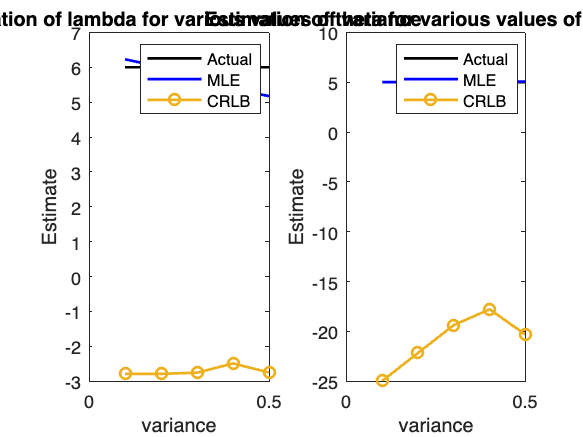

%Varying the variance.
variance_MC=0.1:0.1:0.5;
N=100;

lambda_MLE_est=[];
theta_MLE_est=[];
lambda_crlb=[];
theta_crlb=[];

for iter=1:size(variance_MC,2)
    lambda_MLE=[];
    theta_MLE=[];
    CRLB_lambda=[];
    CRLB_k=[];

    for runs=1:MC
        n=0:N-1;
        variance = variance_MC(iter);
        wn = randn(N,1)*variance;
        % Generate a new random sample for each Monte Carlo run
        X = wblrnd(theta_true, lambda_true, N, 1) + wn;

        % Compute the elements of the Fisher information matrix
        I_lambda_lambda = -mean(dlnL_dlambda(lambda_true, theta_true, X).^2);
        I_k_k = -mean(dlnL_dk(lambda_true, theta_true, X).^2);
        I_lambda_k = -mean(dlnL_dlambda(lambda_true, theta_true, X).*dlnL_dk(lambda_true, theta_true, X));

        % Compute the inverse of the Fisher information matrix
        FIM = [I_lambda_lambda I_lambda_k; I_lambda_k I_k_k];
        invFIM = inv(FIM);

        % Compute the Cramer-Rao lower bound for lambda and theta
        CRLB_lambda = [CRLB_lambda invFIM(1,1)];
        CRLB_k = [CRLB_k invFIM(2,2)];

        %Maximum Likelihood Estimation.

        %Newton-Raphson Method for lambda.
        lambda_est= newton_raphson_lambda(theta_true,N,X,3,tol);
        lambda_MLE=[lambda_MLE lambda_est];

        %Closed form solution for theta.
        theta_est = ((1/N)*sum(X.^lambda_est))^(1/lambda_est);
        theta_MLE=[theta_MLE theta_est];
    end
    lambda_crlb=[lambda_crlb mean(CRLB_lambda)];
    theta_crlb=[theta_crlb mean(CRLB_k)];


    lambda_MLE_est=[lambda_MLE_est mean(lambda_MLE)];
    theta_MLE_est=[theta_MLE_est mean(theta_MLE)];
end

%Plotting the estimated lambda and theta for various values of initial lambda.
figure;
subplot(1,2,1);
plot(variance_MC,ones(1,size(variance_MC,2))*lambda_true,'k','LineWidth',1.5);
hold on;
plot(variance_MC,lambda_MLE_est,'b','LineWidth',1.5);
hold on;
plot(variance_MC,lambda_crlb,'o-','LineWidth',1.5);
hold off;
legend('Actual','MLE','CRLB');
title('Estimation of lambda for various values of variance');
xlabel('variance');
ylabel('Estimate');
%ylim([-0.3 0.3]);
subplot(1,2,2);
plot(variance_MC,ones(1,size(variance_MC,2))*theta_true,'k','LineWidth',1.5);
hold on;
plot(variance_MC,theta_MLE_est,'b','LineWidth',1.5);
hold on;
plot(variance_MC,theta_crlb,'o-','LineWidth',1.5);
hold off;
legend('Actual','MLE','CRLB');
title('Estimation of theta for various values of variance');
xlabel('variance');
ylabel('Estimate');

function [lambda] = newton_raphson_lambda(theta,N,x,lambda,tol)
temp=lambda;
i = 0;

while i ==0
    g = (N/lambda)-(N*log(theta))+sum(log(x))-sum((x./theta).^(lambda).*log(x./theta));
    g1 = (-N/lambda^2)-sum((x./theta).^(lambda).*log(x./theta).^2);
    update=g/(g1);
    lambda=temp-update;
    if abs(lambda - temp) < tol
        break;
    end
    temp=lambda;
end
end